## Algorithm Validation

8/1/2024

This livescript will constitute the work in section Results, subsection "Validation of method" in the paper. We will perform a number of tests that will computationally establish the validity and bounds of usability of our method. 

#### Test 1

Notion ID: 34

Methodology: We will choose 6 representative arm base-curves and 3 different arm designs, and sample 1000 different test tip-loads from a uniform distribution. For each of of these 6x3x1000=18,000 test cases, we will compare the results of our algorithm (should take 0.02ms) to the results of a naive search for attainability (should take 0.4ms). Over 18,000 test-cases we expect this to take 7560 seconds, or 2hours and 6 minutes. 

% TODO: refactor the code to support variable-width arms
% Define arm base curve
% First we define the arm's design
rho_outer = 0.08;
rho_inner = 0.015;

rhos = [-rho_outer, -rho_inner, rho_inner, rho_outer];
mat_A = [
    1, 1, 1, 1;
    0, 0, 0, 0;
    -rhos;
    ];

f_bellow = @JacobBellowMechanics.actuator_force;
f_muscle = @GinaMuscleMechanics.actuatorForce_key;
fs = {f_bellow, f_muscle, f_muscle, f_bellow};

l_0 = 0.5;

g_0 = Pose2.hat([0, 0, -pi/2]);
N_poses = 10;

p_bounds = [50; 100; 100; 50];

% Combine the design parameters into a struct
struct_design = struct();
struct_design.mat_A = mat_A;
struct_design.l_0 = l_0;
struct_design.fs = fs;
struct_design.g_0 = g_0;
struct_design.rhos = rhos;
struct_design.p_bounds = p_bounds;

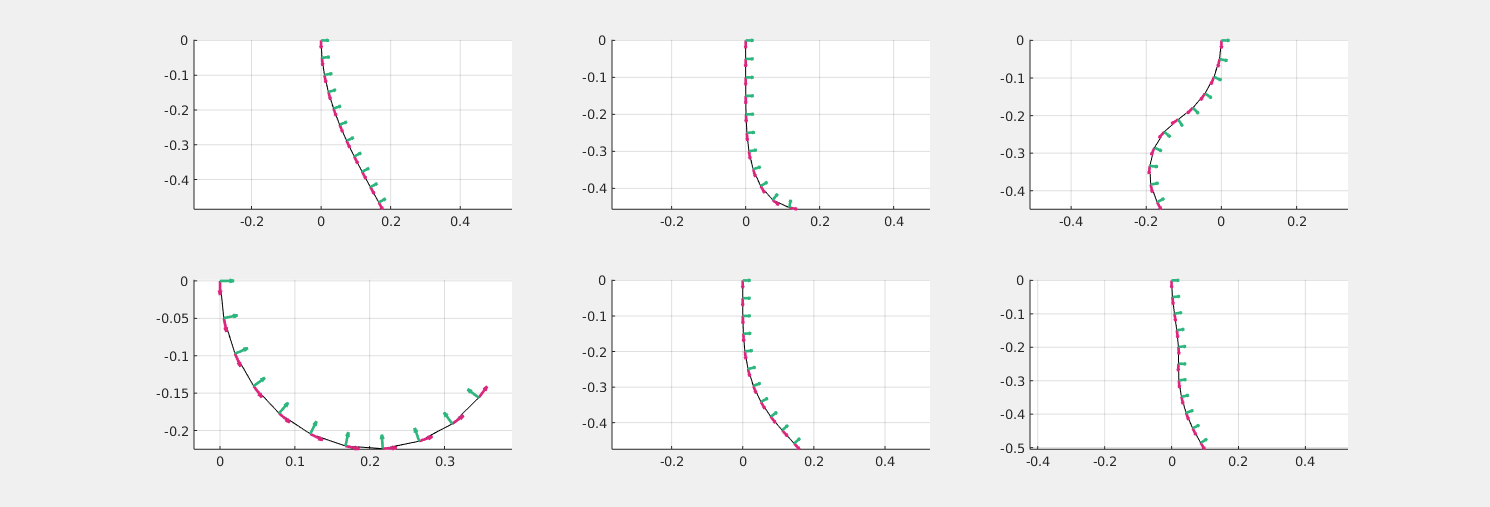

% Generate test cases
l = 0.5;

f_affine_curvature = @(s, a, b) [
    l*ones(size(s)); % TODO: This seems suspect - but for these tests it's really hard to consider what this should be
    zeros(size(s));
    a*s + b
    ];

f_cubic_curvature = @(s, a, b, c, d) [
    l*ones(size(s));
    zeros(size(s));
    a*s.^3 + b*s.^2 + c*s + d;
    ];

s = linspace(0, 1, N_poses);

% TODO: maybe rewrite this to just be a stack of matrices?
cell_segment_twists = cell(2, 3);

cell_segment_twists{1, 1} = f_affine_curvature(s, -1, 1);
cell_segment_twists{2, 1} = f_affine_curvature(s, 1, 2);

cell_segment_twists{1, 2} = f_cubic_curvature(s, 5, 0, 0, 0);
cell_segment_twists{2, 2} = f_cubic_curvature(s, -10, 10, 0, 0);

% Discontinuous cases
cell_segment_twists{1, 3} = [
    l*ones(size(s));
    zeros(size(s));
    (1 - round(s)).*-2 + (round(s) .* 3)
    ];

cell_segment_twists{2, 3} = [
    l*ones(size(s));
    zeros(size(s));
    (1 - round(s)).*(-5*s+1) + (round(s) .* (-s+2))
    ];

cell_segment_twists = transpose(cell_segment_twists);

figure("Visible", true, "Position", [0, 0, 1500, 500])
for i = 1 : numel(cell_segment_twists)
    ax = subplot(2, 3, i);
    segment_twists_ij = cell_segment_twists{i};
    poses = calc_poses(g_0, segment_twists_ij);
    plot_poses(poses, ax);
    grid on
end

% For each arm, test N number of different test reactions and see how many
% are predicted to be attainable by our method

% First we generate the tip loads
F_x_scale = 20;
F_y_scale = 20;
tau_scale = 5;
K_scales = diag([F_x_scale, F_y_scale, tau_scale]);

rng(100);
N_test_Qs = 300;
Q_tests = K_scales* (rand(3, N_test_Qs) - 0.5);

% For each tip load, compute the corresponding loads that they induce 
% at each point along the lengths of each above arm

cell_q_tests = cell(size(cell_segment_twists));
all_q_test_traces_f = zeros(N_poses, N_test_Qs, numel(cell_segment_twists));
all_q_test_traces_m = zeros(N_poses, N_test_Qs, numel(cell_segment_twists));
for i_arm = 1 : numel(cell_segment_twists)
    cell_q_tests{i_arm} = zeros(3, N_poses, N_test_Qs);
    segment_twists_i = cell_segment_twists{i_arm};
    
    for i_test = 1 : N_test_Qs
        Q_test_i = Q_tests(:, i_test);
        cell_q_tests{i_arm}(:, :, i_test) = calc_external_wrench(segment_twists_i, Q_test_i, g_0);
    end
    
    [all_q_test_traces_f(:, :, i_arm), all_q_test_traces_m(:, :, i_arm)] = mat_wrenches_to_traces(cell_q_tests{i_arm});
end

% Sample points from the edges of the pressure space to visualize the
% regions of attainable reaction
N_ps_per_edge = 5;
ps_edges = sample_edges_of_cuboid(N_ps_per_edge, p_bounds);
N_ps = size(ps_edges, 2);

all_bndry_traces_f = zeros(N_poses, N_ps, numel(cell_segment_twists));
all_bndry_traces_m = zeros(N_poses, N_ps, numel(cell_segment_twists));
for i_arm = 1 : numel(cell_segment_twists)
    [bndry_traces_f, bndry_traces_m] = compute_reaction_traces(ps_edges, cell_segment_twists{i_arm}, struct_design);
    
    all_bndry_traces_f(:, :, i_arm) = bndry_traces_f;
    all_bndry_traces_m(:, :, i_arm) = bndry_traces_m;
end

% For each arm design and proposed load, check if our algorithm says it
% should be attainable

cell_attainable = cell(size(cell_segment_twists));

tic
for i_arm = 1 : numel(cell_segment_twists)
    v_attainable = zeros(N_test_Qs, 1);
    q_tests_i = cell_q_tests{i_arm};
    segment_twists_i = cell_segment_twists{i_arm};
    
    for i_load = 1 : N_test_Qs
        q = q_tests_i(:, :, i_load);
        v_attainable(i_load) = check_reactions_attainable_fast(q, segment_twists_i, struct_design, p_bounds);
    end
    cell_attainable{i_arm} = v_attainable;
end
toc

Elapsed time is 26.911584 seconds.


It appears that of the 100 tip loads that we've randomly sampled, none of them are attainable. This is to be expected as it is unlikely for an arbitrary polynomial curvature to be attainable by an arm. Howevever, it would be good to know how far off we are.

#### Analysis 1.1

We will visualize the absolute and relative attainability test results to understand just how "unattainable" the above examples are.

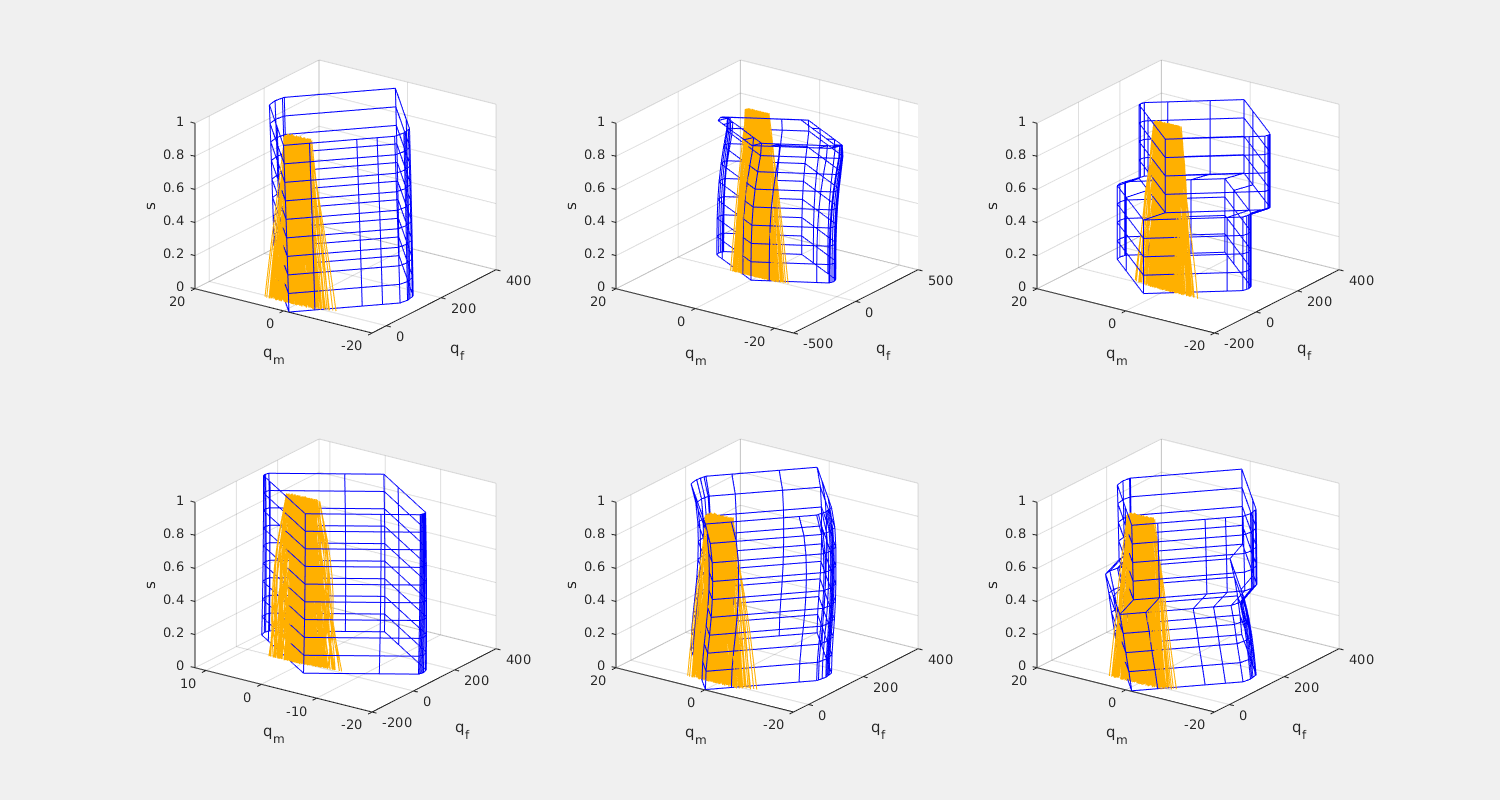

% For each arm, plot how close the reaction requirements are to both the
% prism and cone tests - ie estimate the absolute and relative
% attainability
mat_s = repmat(s, [N_ps, 1]);
mat_s_Q_samples = repmat(s, [N_test_Qs, 1]);

figure("Visible", true, "Position", [0, 0, 1500, 800])
yellow = [255 176 0] / 255;
for i_arm = 1 : numel(cell_segment_twists)
    subplot(2, 3, i_arm);
    
    i_bndry = boundary(squeeze(all_bndry_traces_f(1, :, i_arm))', squeeze(all_bndry_traces_m(1, :, i_arm))', 0);
    
    hold on
    plot3(all_bndry_traces_f(:, i_bndry, i_arm)', all_bndry_traces_m(:, i_bndry, i_arm)', s, 'b');
    plot3(all_bndry_traces_f(:, i_bndry, i_arm)', all_bndry_traces_m(:, i_bndry, i_arm)', mat_s(i_bndry, :), 'b');
    plot3(all_q_test_traces_f(:, : ,i_arm), all_q_test_traces_m(:, : ,i_arm), mat_s_Q_samples', "color", yellow)
    
    xlabel("q_f")
    ylabel("q_m")
    zlabel("s")
    grid on
    view(-55, 25)
end

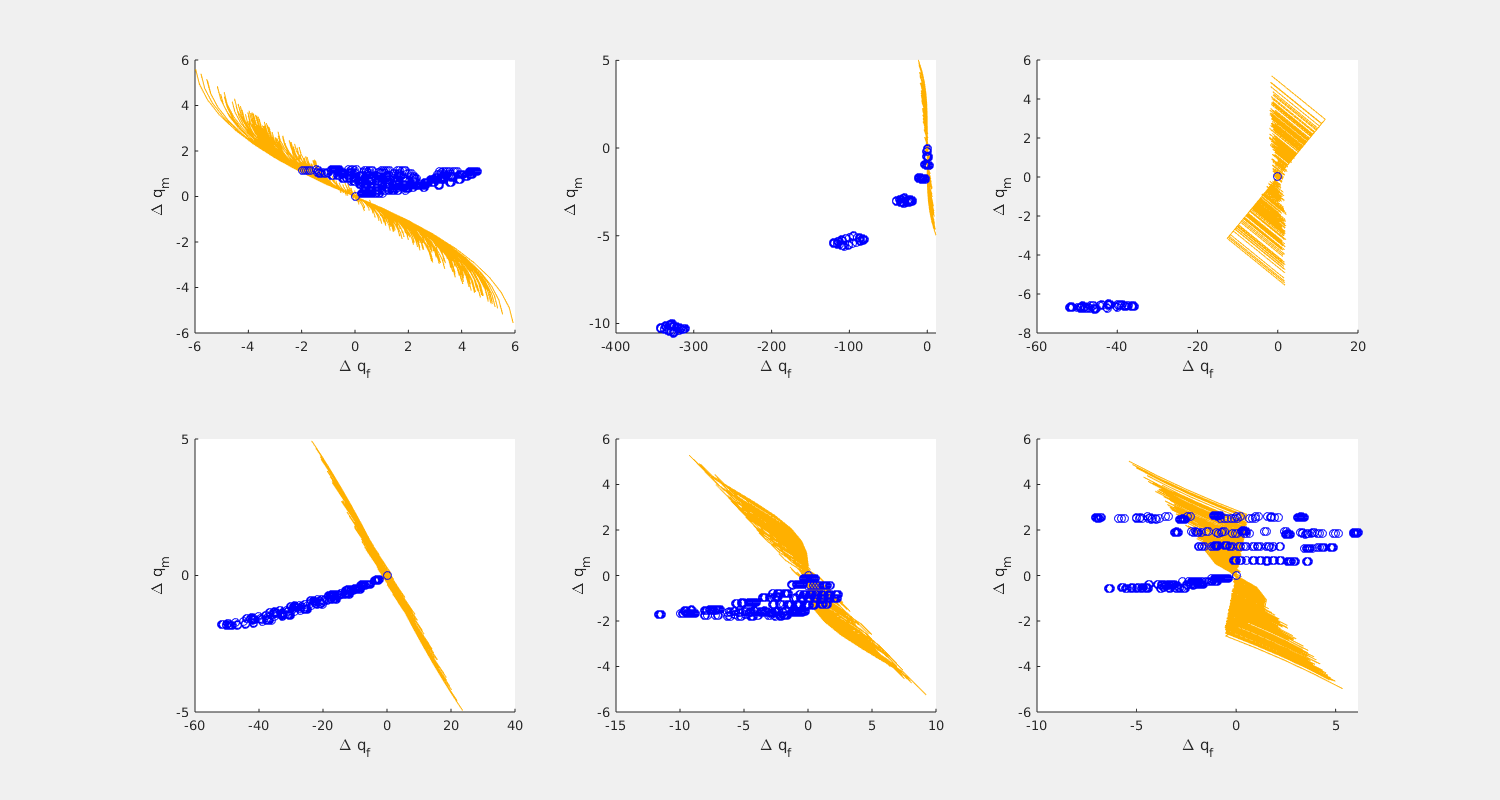

figure("Visible", true, "Position", [0, 0, 1500, 800]);
relative_qf_test_all = all_q_test_traces_f(:, :, :) - all_q_test_traces_f(1, :, :);
relative_qm_test_all = all_q_test_traces_m(:, :, :) - all_q_test_traces_m(1, :, :);

relative_af_bndry_all = all_bndry_traces_f(:, :, :) - all_bndry_traces_f(1, :, :);
relative_am_bndry_all = all_bndry_traces_m(:, :, :) - all_bndry_traces_m(1, :, :);

for i_arm = 1 : numel(cell_segment_twists)
    subplot(2, 3, i_arm);

    % Plot displacements of the external load
    hold on
    plot(relative_qf_test_all(:, :, i_arm), relative_qm_test_all(:, :, i_arm), color=yellow);
    plot(relative_af_bndry_all(:, :, i_arm), relative_am_bndry_all(:, :, i_arm), "o", color='b');
    xlabel("\Delta q_f")
    ylabel("\Delta q_m")
    set(gcf, "Visible", true)
end

% Compute how "unattainable" we are for one of these test cases
tic
[min_dists, closest_pts, weights] = calc_attainability_metric( ...
    relative_qf_test_all(:, :, 1), ...
    relative_qm_test_all(:, :, 1), ...
    relative_af_bndry_all(:, :, 1), ...
    relative_am_bndry_all(:, :, 1) ...
);
toc

Elapsed time is 100.010474 seconds.


It would be interesting to know which load had the lowest unattainability / highest attainability

[min_min_dist, i_min] = min(sum(min_dists, 1))

min_min_dist = 3.2145

i_min = 134

Thus the given shape is the most attainable when the 44th tip load is applied to it. 

It is also useful to consider the distribution of unattainability metrics. 

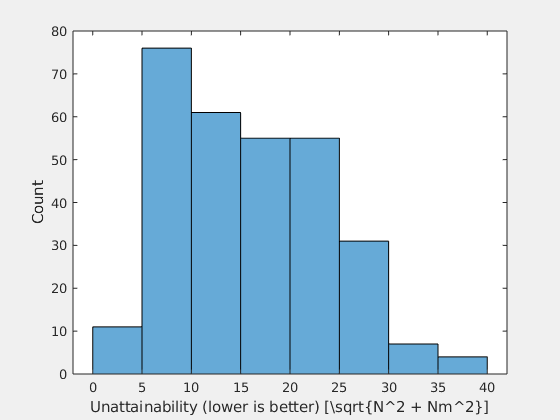

figure("Visible", true);
histogram(sum(min_dists, 1));
xlabel("Unattainability (lower is better) [\sqrt{N^2 + Nm^2}]")
ylabel("Count")

For a given reaction requirement trace, we can now visualize the series of points in attainable sets that are closest to it, and visualize the difference between them.

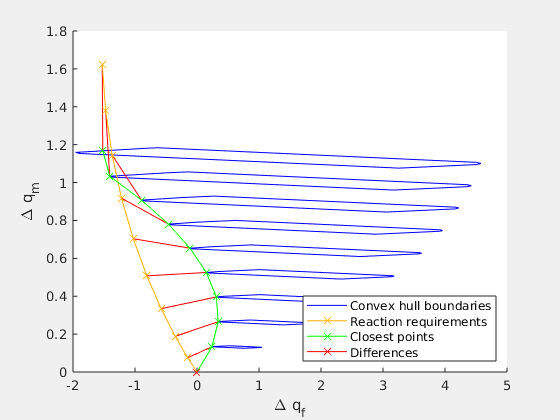

i_arm_plot = 1;     % Index of the arm base-curve to plot
i_q_plot = 44;       % Index of the reaction requirement to plot

figure("Visible", true)
hold on

plot(0, 0, "b", displayname="Convex hull boundaries")
for i = 2 : N_poses
    i_conv_hull = boundary(relative_af_bndry_all(i, :, i_arm_plot)', relative_am_bndry_all(i, :, i_arm_plot)', 0);
    plot(relative_af_bndry_all(i, i_conv_hull, i_arm_plot)', relative_am_bndry_all(i, i_conv_hull, i_arm_plot)', "-", color="b", handlevisibility="off");
end

closest_pairs_f = [relative_qf_test_all(:, i_q_plot, i_arm_plot)'; closest_pts(1, :, i_q_plot)];
closest_pairs_m = [relative_qm_test_all(:, i_q_plot, i_arm_plot)'; closest_pts(2, :, i_q_plot)];
plot(closest_pairs_f, closest_pairs_m, "rx-", handlevisibility="off");

plot(relative_qf_test_all(:, i_q_plot, i_arm_plot), relative_qm_test_all(:, i_q_plot, i_arm_plot), "x-", color=yellow, displayname="Reaction requirements");
plot(closest_pts(1, :, i_q_plot), closest_pts(2, :, i_q_plot), "x-", color="green", displayname="Closest points");
plot(0, 0, 'rx-', displayname="Differences")

legend(location="southeast")
xlabel("\Delta q_f")
ylabel("\Delta q_m")

min_dists(:, i_q_plot)

ans =          0
    0.3962
    0.6979
    0.8930
    0.9606
    0.9158
    0.7693
    0.5303
    0.3551
    0.4572


sum(min_dists(:, i_q_plot))

ans = 5.9753

#### Analysis 1.2

Consider the most attainable tip load - the one that minimizes the sum-of-distances to its closest points in the attainable sets. In the above example we have found that reaction requirement 44 is the most attainable. Where does its corresponding tip-load sit in the space of tip-loads? What is its pre-image?

color_gray = [150,150,150]/255;
color_yellow = [255 176 0] / 255

color_yellow =     1.0000    0.6902         0


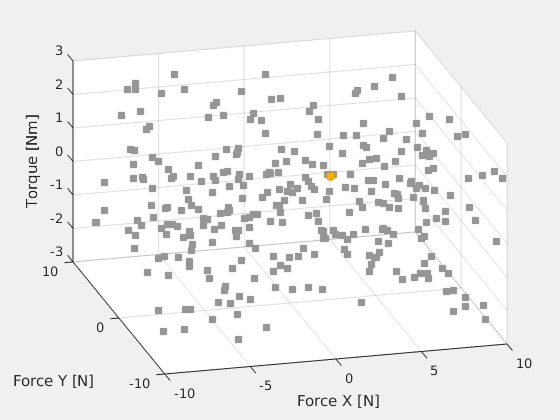

figure("Visible", true);
hold on
plot3(Q_tests(1, :), Q_tests(2, :), Q_tests(3, :), "square", color=color_gray, markerfacecolor=color_gray);
plot3(Q_tests(1, i_min), Q_tests(2, i_min), Q_tests(3, i_min), "o", markerfacecolor=color_yellow, color=color_yellow);
grid on
xlabel("Force X [N]")
ylabel("Force Y [N]")
zlabel("Torque [Nm]")
view(-115, 40)

#### Test 1b

#### Test 2

Notion ID: 40

**Purpose:** Demonsetrate the attainability metric's use for selecting arm base-curve geometries to target for. 

**Methodology:** For a target task, consider a tip pose target and load requirement combination. Consider 5 representative base-curves for reaching the tip pose target, and compare the attainability of each. 